# Are the Roundworms Alive or Dead?

This example uses transfer learning to train a deep network that can classify images of roundworms as either alive or dead. (Alive worms are round; dead ones are straight.)

## Get the training images and classes

Create a datastore to the images.

imds = imageDatastore('deeplearning_course_files/Roundworms/WormImages');

Get the known classifications from a file and use these as the image labels.

groundtruth = readtable('WormData.csv');
imds.Labels = categorical(groundtruth.Status);

View the first few images. The second argument to `imshow` scales the display based on the range of pixel values in the image.

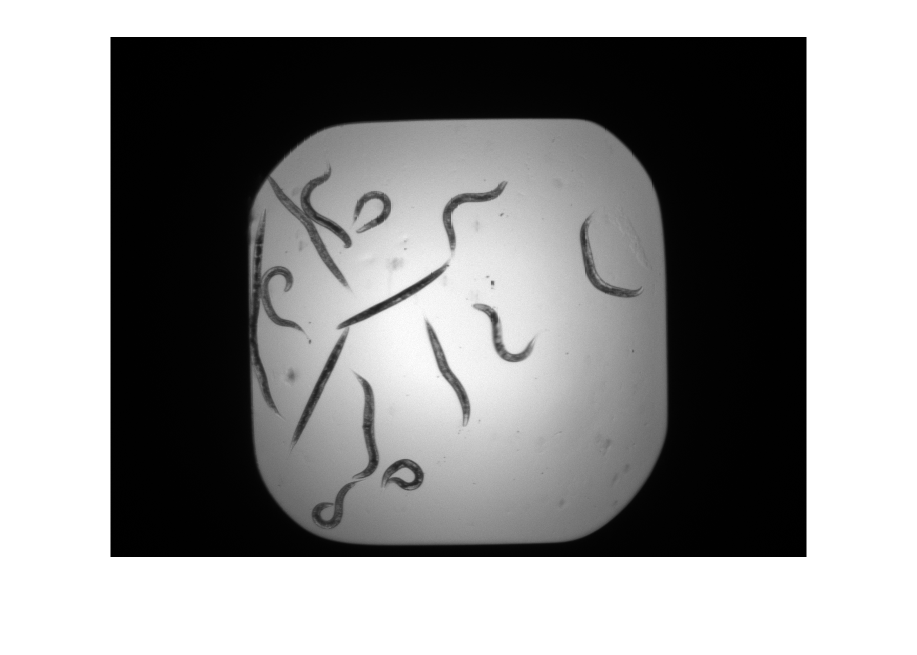

imshow(readimage(imds,1),[])

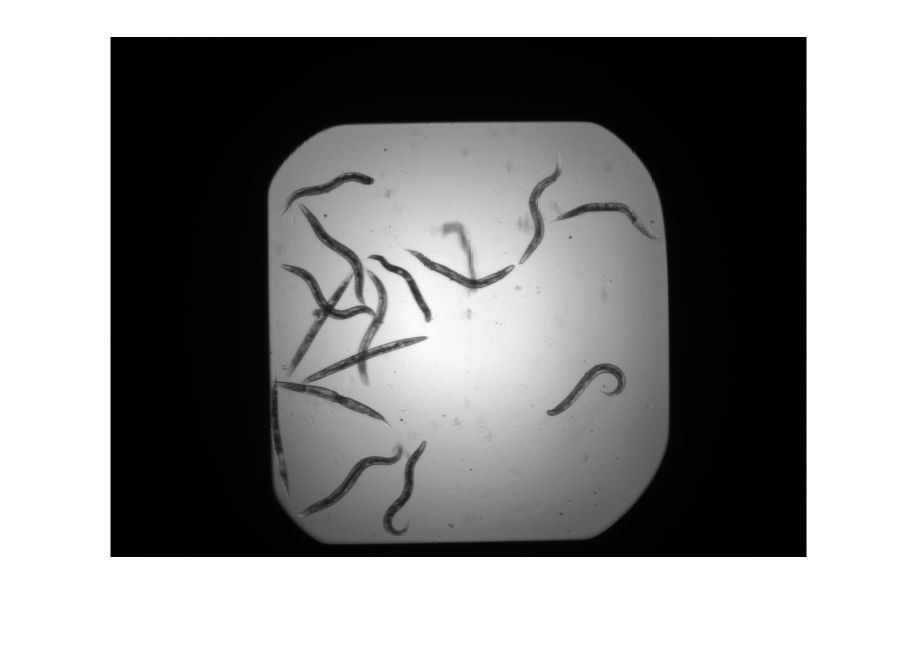

imshow(readimage(imds,2),[])

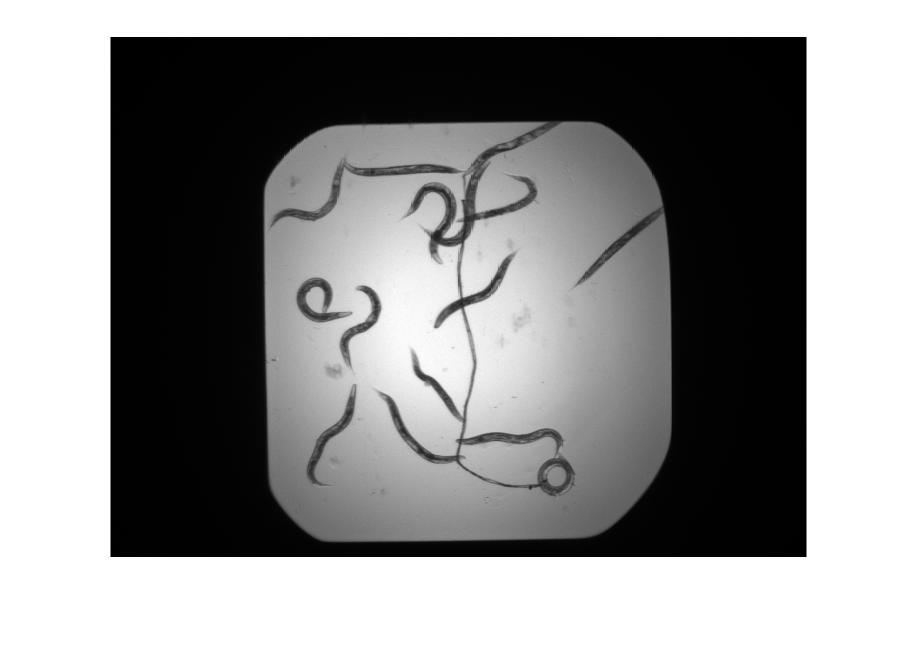

imshow(readimage(imds,3),[])

Divide data into training (60%) and testing (40%) sets

[trainImgs,testImgs] = splitEachLabel(imds,0.6,'randomized');

Create augmented image datastores to preprocess the images.

trainds = augmentedImageDatastore([227 227],trainImgs,'ColorPreprocessing','gray2rgb');
testds = augmentedImageDatastore([227 227],testImgs,'ColorPreprocessing','gray2rgb');

## Build a network

Start with a pretrained network

net = alexnet;

Take the CNN layers and add new classification layers at the end.

prebuiltLayers = net.Layers(1:end-3);
layers = [prebuiltLayers;fullyConnectedLayer(2);softmaxLayer;classificationLayer];

## Set some training options

topts = trainingOptions('sgdm','InitialLearnRate',0.0001, 'MiniBatchSize',8);

## Train the network

wormsnet = trainNetwork(trainds,layers,topts)

Training on single GPU.
Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:00 |       75.00% |       0.5194 |      1.0000e-04 |
|       8 |          50 |       00:00:14 |      100.00% |       0.0552 |      1.0000e-04 |
|      15 |         100 |       00:00:29 |      100.00% |       0.0181 |      1.0000e-04 |
|      22 |         150 |       00:00:44 |      100.00% |       0.0084 |      1.0000e-04 |
|      29 |         200 |       00:00:58 |      100.00% |       0.0008 |      1.0000e-04 |
|      30 |         210 |       00:01:01 |      100.00% |       0.0002 |      1.0000e-04 |
|===============================

wormsnet =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


## Evaluate network on test data

Make predictions

preds = classify(wormsnet,testds)

preds = 37×1 categorical array
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     dead 
     dead 
     dead 
     dead 
     dead 
     dead 
     dead 
     alive 
     alive 
     alive 
     alive 
     alive 
     alive 
     dead 
     alive 
     dead 
     dead 
     dead 


Compare with reality

truetest = testImgs.Labels;
nnz(preds == truetest)/numel(preds)

ans = 0.9730

View confusion matrix

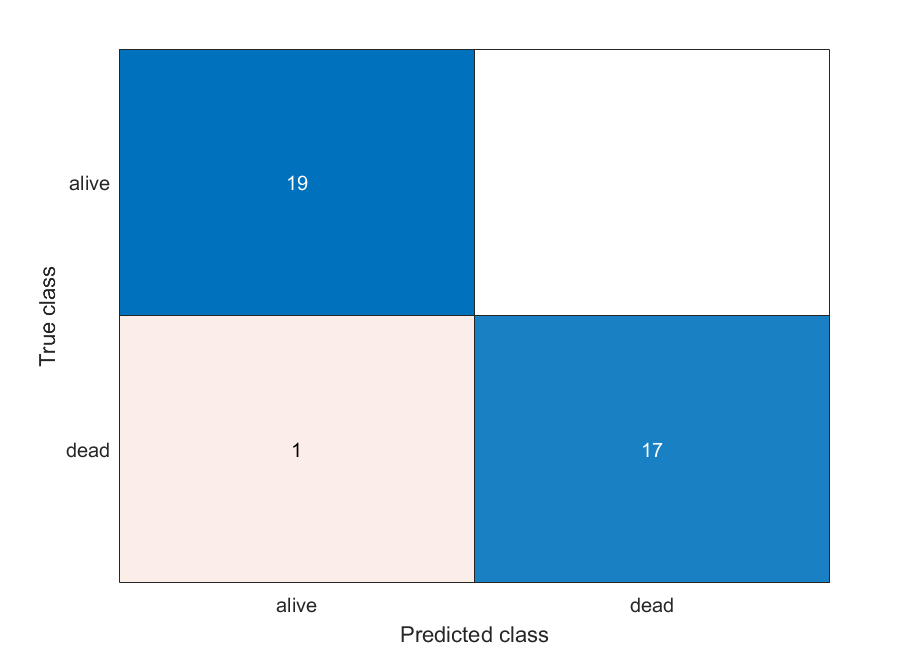

confusionchart(truetest,preds);